# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
% which 
%conf = 'CSNESiteVisit';
%conf = 'NeuroModulation';
%conf = 'NeuroModulationV2';

conf = 'NeuroModulationV3';

% 6/17/_2016 try neuromdoulation 
for i = 2:length(SIDS)-2
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                

                            if (strcmp(conf,'NeuroModulation') | strcmp(conf,'NeuroModulationV2')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                tB = [tB tempBase'];
                t1 = [t1 tempResp1'];
                t2 = [t2 tempResp2'];
                t3 = [t3 tempResp3'];
                            else
                            tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
            end
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            
            % 6-17-2016 - have to transpose for 'conf'
                            if (strcmp(conf,'NeuroModulation') | strcmp(conf,'NeuroModulationV2')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                           typeResp = [tempResp3' tempResp2' tempResp1' tempBase'];
            else
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            end
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =    1.0e-26 *

    0.2988
         0


tbl =     'Source'           'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'             'Prob>F'    
    'anovaNumStims'    [5.1662e+04]    [   3]    [        0]    [1.7221e+04]    [   42.4744]    [2.9878e-27]
    'anovaBetaSID'     [8.3511e+06]    [   6]    [        0]    [1.3919e+06]    [3.4330e+03]    [         0]
    'Error'            [3.7275e+06]    [9194]    [        0]    [  405.4324]              []              []
    'Total'            [1.2533e+07]    [9203]    [        0]              []              []              []


stats =          source: 'anovan'
          resid: [9204x1 double]
         coeffs: [12x1 double]
            Rtr: [10x10 double]
       rowbasis: [10x12 double]
            dfe: 9194
            mse: 405.4324
    nullproject: [12x10 double]
          terms: [2x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [3x1 double]
     coeffnames: {12x1 cell}
           vars: [12x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


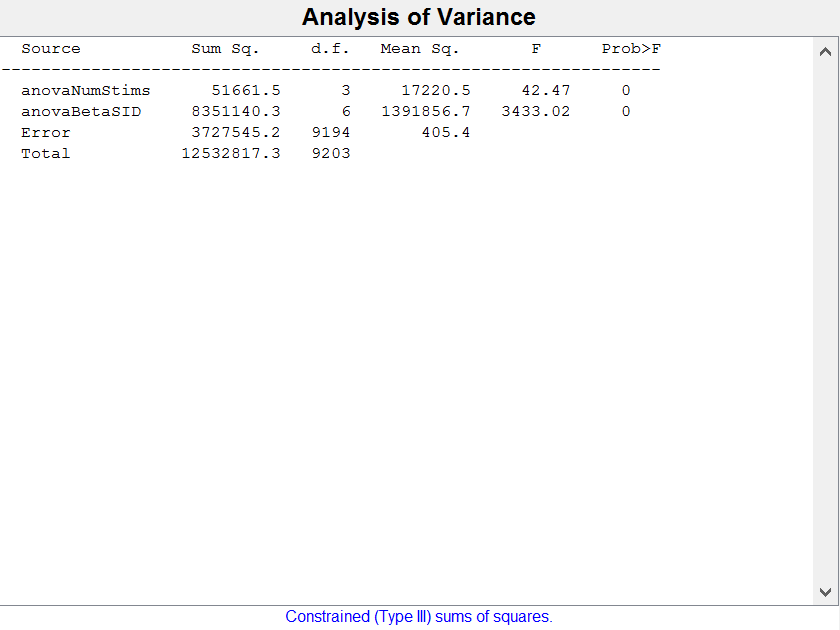

figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'})
% 
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})

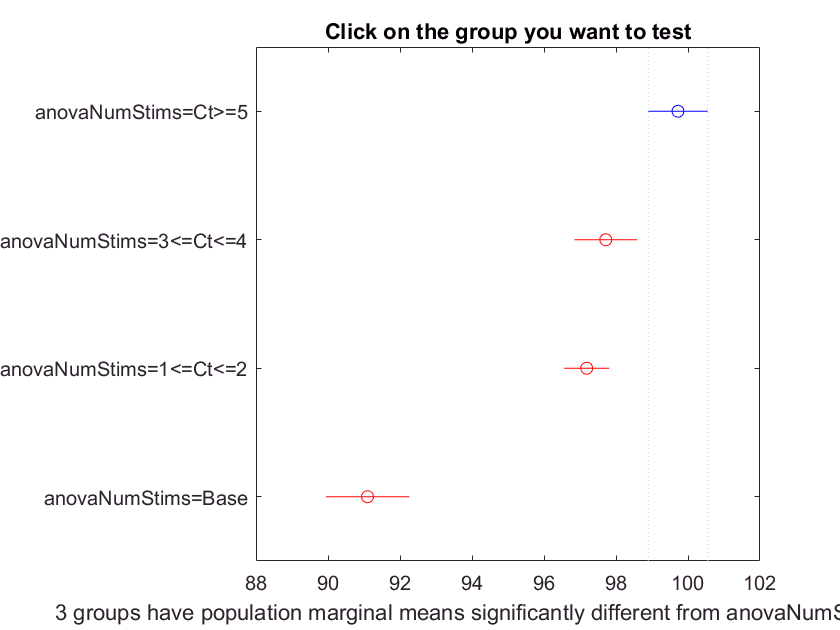

c =     1.0000    2.0000    0.3036    2.0060    3.7083    0.0132
    1.0000    3.0000    1.0869    2.5361    3.9853    0.0000
    1.0000    4.0000    6.6391    8.6244   10.6097    0.0000
    2.0000    3.0000   -0.9611    0.5301    2.0213    0.7978
    2.0000    4.0000    4.5952    6.6184    8.6416    0.0000
    3.0000    4.0000    4.2919    6.0883    7.8846    0.0000


m =    99.7214    0.4653
   97.7155    0.4904
   97.1853    0.3250
   91.0970    0.6271


h =   Figure (5: Multiple comparison of population marginal means) with properties:

      Number: 5
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


% [p,tbl,stats] = anovan(anova2,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% 

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [99.7214]    [0.4653]
    'anovaNumStims=3<=Ct<=4'    [97.7155]    [0.4904]
    'anovaNumStims=1<=Ct<=2'    [97.1853]    [0.3250]
    'anovaNumStims=Base'        [91.0970]    [0.6271]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [90 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [90 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [90 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


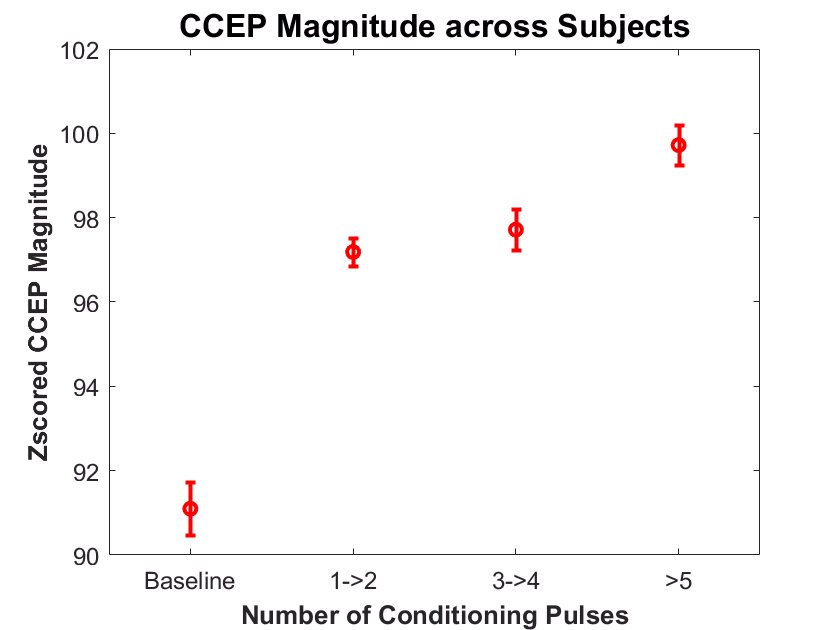

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

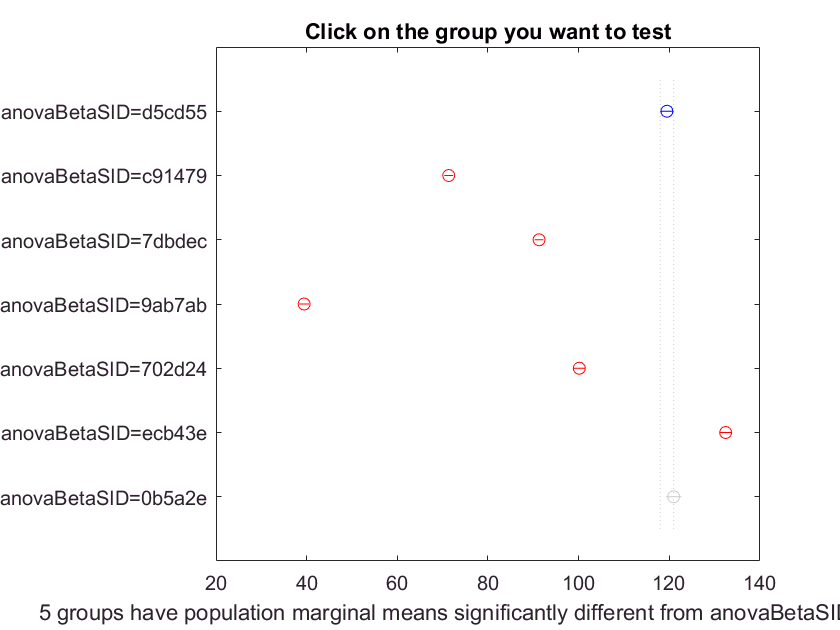

results1 =     1.0000    2.0000   45.6779   48.1309   50.5839    0.0000
    1.0000    3.0000   25.7313   28.1992   30.6670    0.0000
    1.0000    4.0000   77.4607   80.0299   82.5990    0.0000
    1.0000    5.0000   16.5028   19.3274   22.1521    0.0000
    1.0000    6.0000  -15.6704  -12.9638  -10.2573    0.0000
    1.0000    7.0000   -4.6090   -1.4741    1.6608    0.8094
    2.0000    3.0000  -21.8672  -19.9318  -17.9964    0.0000
    2.0000    4.0000   29.8524   31.8989   33.9454    0.0000
    2.0000    5.0000  -31.1722  -28.8035  -26.4348    0.0000
    2.0000    6.0000  -63.3016  -61.0948  -58.8879    0.0000



figure
results1 = multcompare(stats,'Dimension',[2])

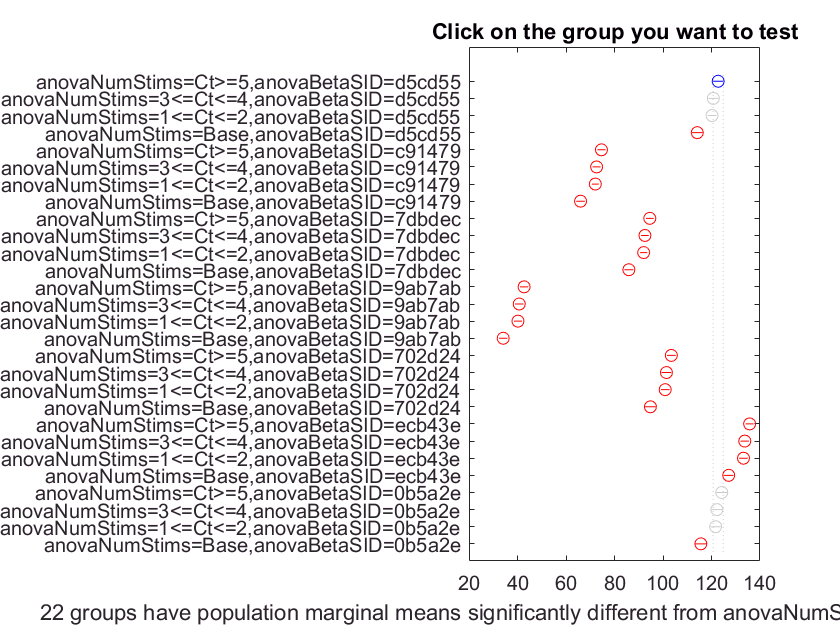

cM =     1.0000    2.0000   -0.4554    2.0060    4.4674    0.3354
    1.0000    3.0000    0.4407    2.5361    4.6314    0.0023
    1.0000    4.0000    5.7539    8.6244   11.4949    0.0000
    1.0000    5.0000   45.0405   48.1309   51.2214    0.0000
    1.0000    6.0000   46.1512   50.1369   54.1226    0.0000
    1.0000    7.0000   46.8339   50.6670   54.5002    0.0000
    1.0000    8.0000   52.5340   56.7553   60.9766    0.0000
    1.0000    9.0000   25.0900   28.1992   31.3083    0.0000
    1.0000   10.0000   26.1521   30.2051   34.2582    0.0000
    1.0000   11.0000   26.7448   30.7353   34.7257    0.0000


mM =   122.7571    0.8548
  120.7511    0.8382
  120.2210    0.7016
  114.1327    0.9232
   74.6261    0.6559
   72.6202    0.6496
   72.0900    0.4961
   66.0017    0.7441
   94.5579    0.6046
   92.5519    0.6231


hM =   Figure (8: Multiple comparison of population marginal means) with properties:

      Number: 8
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaBetaSID=d5cd55'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=d5cd55'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=d5cd55'
    'anovaNumStims=Base,anovaBetaSID=d5cd55'
    'anovaNumStims=Ct>=5,anovaBetaSID=c91479'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=c91479'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=c91479'
    'anovaNumStims=Base,anovaBetaSID=c91479'
    'anovaNumStims=Ct>=5,anovaBetaSID=7dbdec'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=7dbdec'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=7dbdec'
    'anovaNumStims=Base,anovaBetaSID=7dbdec'
    'anovaNumStims=Ct>=5,anovaBetaSID=9ab7ab'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=9ab7ab'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=9ab7ab'
    'anovaNumStims=Base,anovaBetaSID=9ab7ab'
    'anovaNumStims=Ct>=5,anovaBetaSID=702d24'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=702d24'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=702d24'
    'anovaNumStims=Base,anovaBetaSID=702d24'
    'anovaNumStims=Ct>=5,anovaBetaSID=ecb43e'



% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

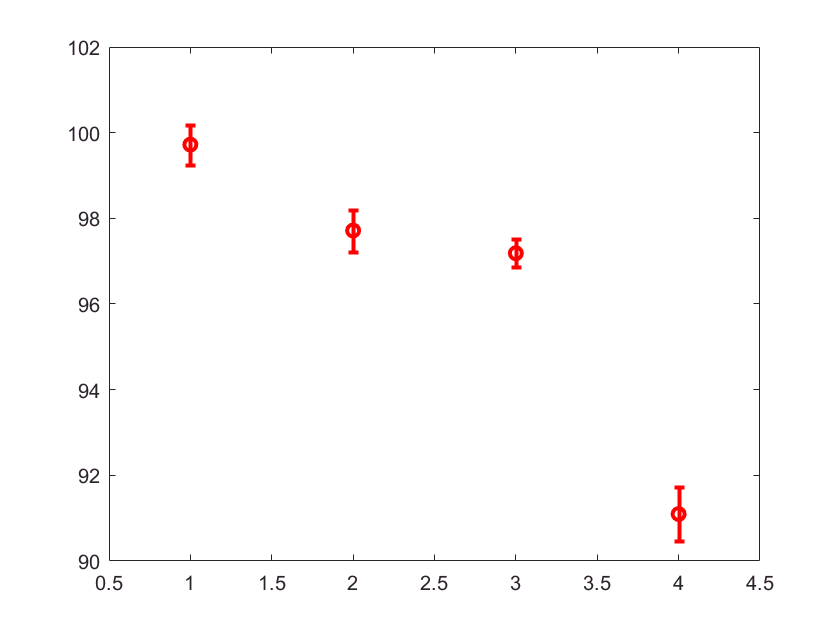

errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')